#### 1. What is the expected appearance of the Fourier transform of the downsampled signal in relation to the Fourier transform of the original signal sbl in Section 3.1? ANSWER:

Lower amplitude but same shape 8 times periodically since we follow sampling theorem.

#### 2. What is the expected appearance of the reconstructing filter in this case, in the signal domain and in the frequency domain? 

translated sinc in the signal domain and then fourier transform of sinc in the frequency domain (rect)

#### 3. How close do you expect the reconstructed signal in Section 3.1 to be relative to the original signal? Why 

Since the signal is band limited within $[-\pi/8
, \pi/8]$ we should be able to reconstruct it even with only every 8th sample so it should be the same.

#### 4. In order to predict the results of adding noise to the samples, you need to assume two critical properties of this noise. Which two properties? Hint: se lecture 2F! 

noise is unbiased and mutually independant

#### 5. What mean and standard deviation do you expect for the error in the reconstructed signal sblrec8n in Section 3.2?

mean 0 and sigma 0.1, the same as the sampling noise.

#### 6. What is the expected appearance of the reconstructing filter in Section 3.3, in the signal domain and in the frequency domain? How does it differ from the previous one?

sinc functions again but closer together since we get sinc(2t-k)

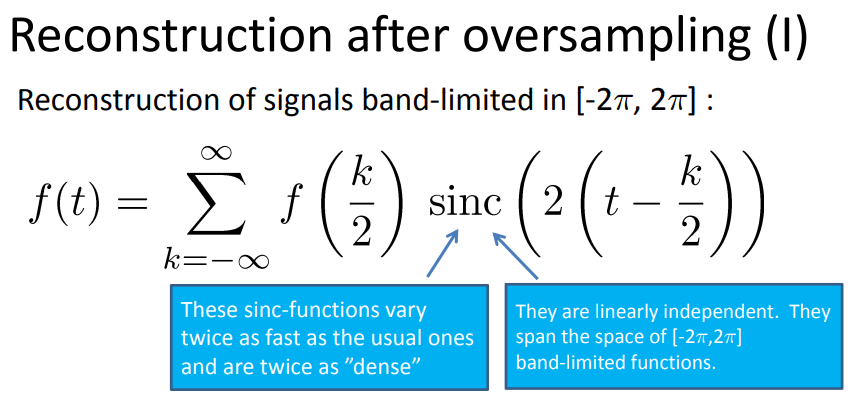

#### 7. What mean and standard deviation do you expect to get when you reconstruct the signal in Section 3.3? Why?

same as 5, no improvement since all the noise is still included

#### 8. In Section 3.3, the reconstructing functions form a basis of some subspace of the signal space. What subspace of the signal space does this basis span? Hint: What is their bandwidth in the frequency domain?

Since the inverse fourier transform of a sinc is a rect they span the frequencies of this rectangles bandwidth, [-pi/4, pi/4]

#### 9. How can you use SVD to verify if a matrix that holds a set of vectors in its column corresponds to a subspace basis or to a subspace frame? 

Use SVD to find if there are any linear combinations between the bases by checking if any of the singular values are 0

#### 10. What mean and standard deviation of the reconstruction error do you expect in Section 3.4? Why? 

mean 0 and std dev 1/sqrt(2)*sigma since we don't add all of the added noise. (lec F slide 33)

#### 11. What is the difference between variance and standard deviation? Are you sure about how you formulated the answer of the previous question?

Variance is standard deviation squared. $Variance = E[n^2]=1/2\sigma^2 => standard dev = 1/\sqrt2\sigma$

#### 12. In Section 3.4, the reconstructing functions form a frame of some subspace of the signal space. What subspace of the signal space does this frame span? Hint: What is their bandwidth in the frequency domain? 

[-pi/8, pi/8]

#### 13. If you get a finite number, k, of samples from a noise source that has zero mean, does this automatically imply that the average of the k samples is equal to zero?

No since if you only have k = 1 and that sample is not 0 then the average is not 0.

#### 14. Given one of the filters in Section 4, e.g., h1, how are the other three filters related to h1 in an orthogonal filter bank? Assume that the filters are real and give the relation between the filters in the signal domain.

filters are real so no need to take conjugate though

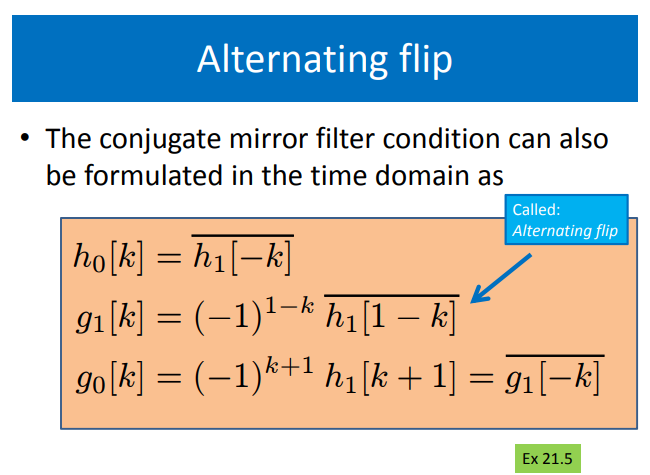

#### 15. Make an illustration of the complete processing structure that is used in Section 4.2 similar to the figure of two-channel filter bank above. The figure should specify what filters are used, and where you find the input and output signals as well as the signals a1, d1, a2, d2 and a1rec.

#### 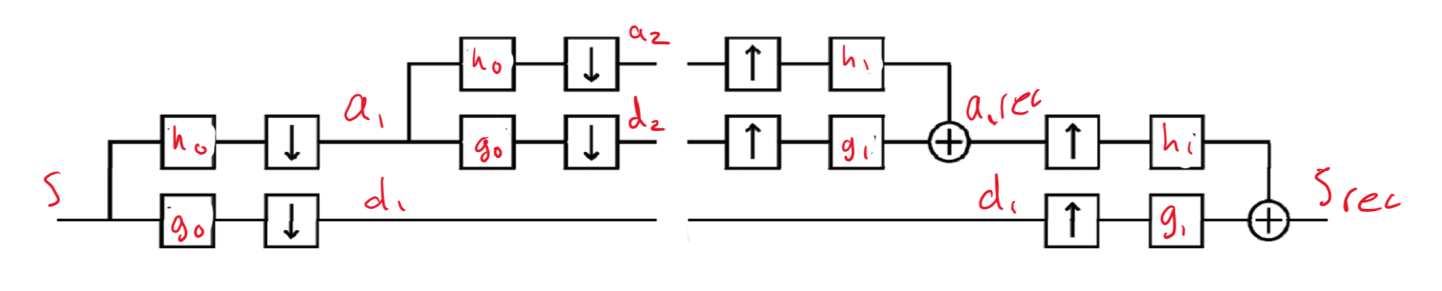

#### 16. Examine the code marked (A) in Section 4.2 and describe what information you will find in the vector ad for each iteration of the for-loop. 

First it is just the signal s and then it is the two-channel filter output a1 and d1 concatenated which is the input for the next level of the multi-level filter bank so you will find a2, d2 and d1 concatenated and so on.

#### 17. Examine the code marked (B) in Section 4.2 and describe what information you will find in the vector ad for each iteration of the for-loop. 

You will find the reconstructed $a_{Nrec
}$ concatenated with $
d_N,d_{N-1}...d_1$in each of them and then at last $s_{rec}$

clear
close all
clf
addpath ExerciseF\

## 3.1 Down-sampling and reconstruction of a discrete signal

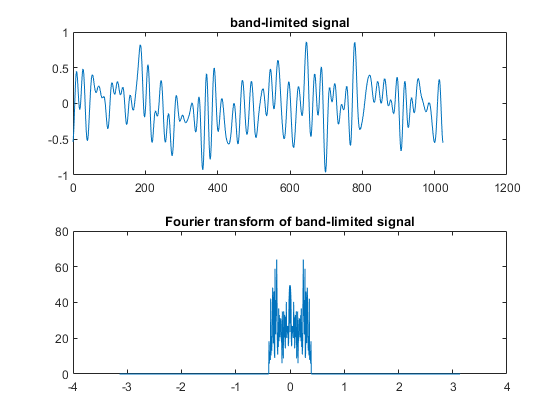

s=randn(1024,1);
S=fftshift(fft(s));
u=(-512:511)'*pi/512;
Rect8=(abs(u)<pi/8);
Sbl=S.*Rect8; %Create a pi/4-band-limited transform
sbl=ifft(ifftshift(Sbl));
figure(1);subplot(2,1,1);plot(0:1023,sbl);
title('band-limited signal');
subplot(2,1,2);plot(u,abs(Sbl));
title('Fourier transform of band-limited signal');

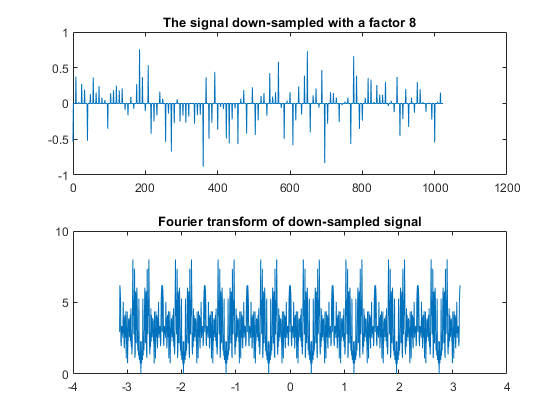


downsampl8=sbl(1:8:end);

upsampl8=zeros(1024,1);
upsampl8(1:8:end)=downsampl8;
figure(2);subplot(2,1,1);plot(0:1023,upsampl8);
title('The signal down-sampled with a factor 8');
subplot(2,1,2);plot(u,abs(fftshift(fft(upsampl8))));
title('Fourier transform of down-sampled signal');

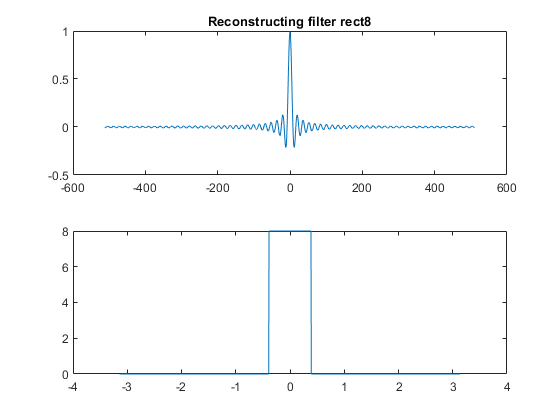


% Construct reconstuction filters
rect8=ifft(fftshift(8*Rect8));
figure(3);
subplot(2,1,1);plot(-512:511,ifftshift(rect8));
title('Reconstructing filter rect8');
subplot(2,1,2);plot(u,abs(fftshift(fft(rect8))));

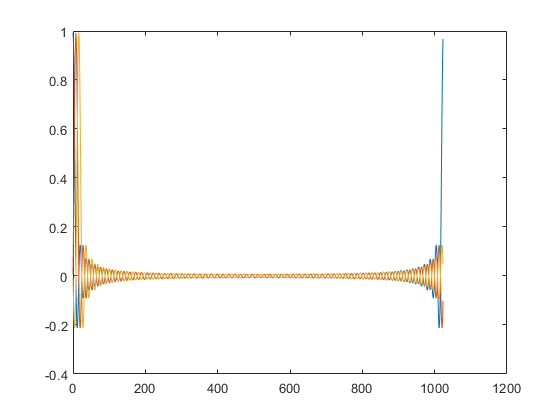


for ix=0:127,
    B8(:,ix+1)=circshift(rect8,8*ix);
end
figure(4);plot(0:1023,B8(:,1:3));

#### QUESTION: What do the reconstructing functions look like? Are they in accordance with your expectations described in preparatory exercise 2? 

Translated sinc functions.

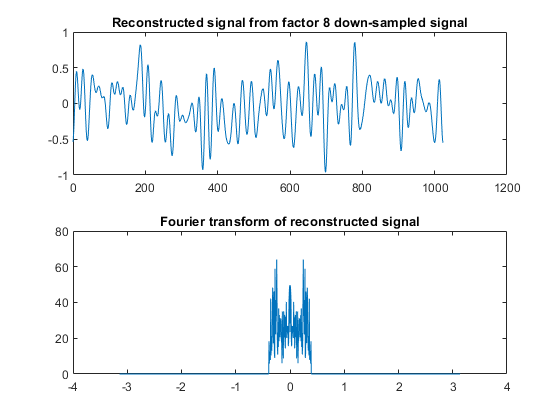

sblrec8=B8*upsampl8(1:8:end);
figure(5);
subplot(2,1,1);plot(0:1023,sblrec8);
title('Reconstructed signal from factor 8 down-sampled signal');
subplot(2,1,2);plot(u,abs(fftshift(fft(sblrec8))));
title('Fourier transform of reconstructed signal');

fprintf('Reconstruction from factor 8 down-sampled signal (no noise)\n');

Reconstruction from factor 8 down-sampled signal (no noise)


fprintf('Reconstruction error: %e\n',norm(sbl-sblrec8));

Reconstruction error: 4.773671e-15


mean(sbl-sblrec8)

ans = 5.6991e-18

std(sbl-sblrec8)

ans = 1.4914e-16

#### QUESTION: What amount of noise do you get (mean and standard deviation)? Is it consistent with your answer to preparatory exercise 3?

Practically no noise. Mean 0 and std 0

## 3.2 Sampling noise 

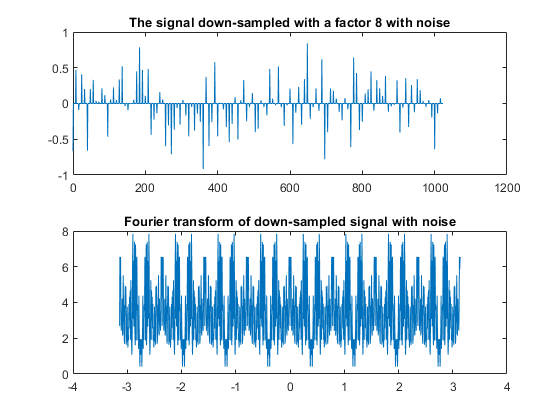

sigma=0.1;
downsampl8n=sbl(1:8:end)+sigma*randn(128,1);
upsampl8n=zeros(1,1024);
upsampl8n(1:8:end)=downsampl8n;
figure(6);
subplot(2,1,1);plot(0:1023,upsampl8n);
title('The signal down-sampled with a factor 8 with noise');
subplot(2,1,2);plot(u,abs(fftshift(fft(upsampl8n))));
title('Fourier transform of down-sampled signal with noise');

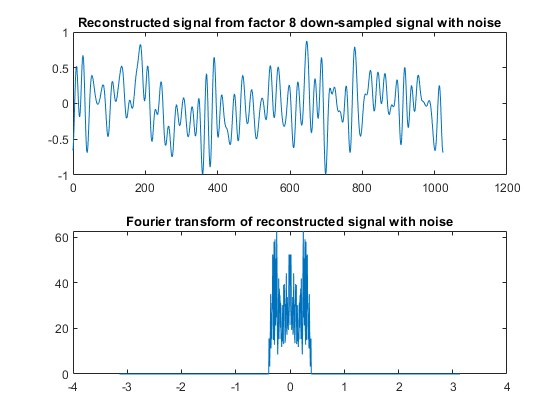


sblrec8n=B8*downsampl8n;
figure(7);subplot(2,1,1);plot(0:1023,sblrec8n);
title('Reconstructed signal from factor 8 down-sampled signal with noise');
subplot(2,1,2);plot(u,abs(fftshift(fft(sblrec8n))));
title('Fourier transform of reconstructed signal with noise');

err=sbl-sblrec8n;
fprintf('Reconstruction from factor 8 down-sampled signal with noise\n');

Reconstruction from factor 8 down-sampled signal with noise


fprintf('Reconstruction error: mean %f std %f\n',mean(err),std(err));

Reconstruction error: mean -0.001898 std 0.107036


#### QUESTION: What amount of noise do you get (mean and standard deviation)? Is it consistent with your answer to preparatory exercise 5? 

Mean 0 and std 0.1

## 3.3 Over-sampling, reconstruction with a basis

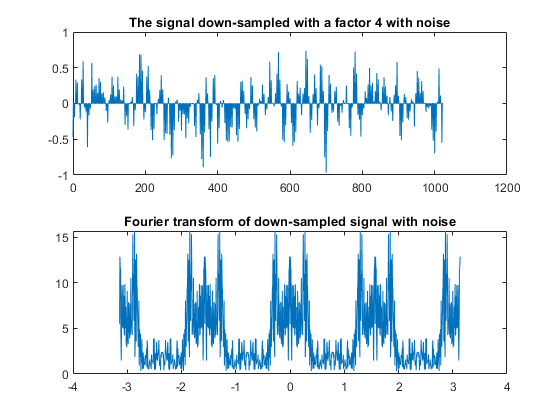

downsampl4n=sbl(1:4:end)+sigma*randn(256,1);
upsampl4n=zeros(1,1024);
upsampl4n(1:4:end)=downsampl4n;
figure(8);
subplot(2,1,1);plot(0:1023,upsampl4n);
title('The signal down-sampled with a factor 4 with noise');
subplot(2,1,2);plot(u,abs(fftshift(fft(upsampl4n))));
title('Fourier transform of down-sampled signal with noise');

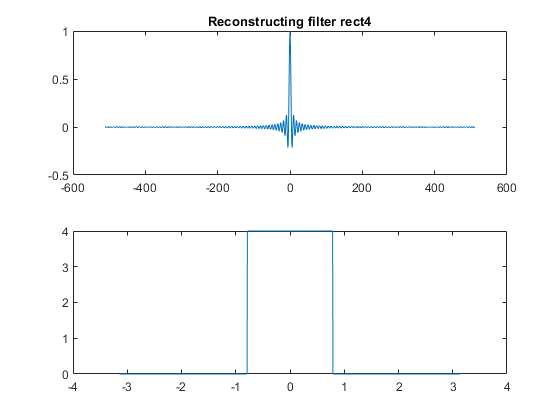


Rect4=(abs(u)<=pi/4);
rect4=ifft(fftshift(4*Rect4));
figure(9);
subplot(2,1,1);plot(-512:511,ifftshift(rect4));
title('Reconstructing filter rect4');
subplot(2,1,2);plot(u,abs(fftshift(fft(rect4))));

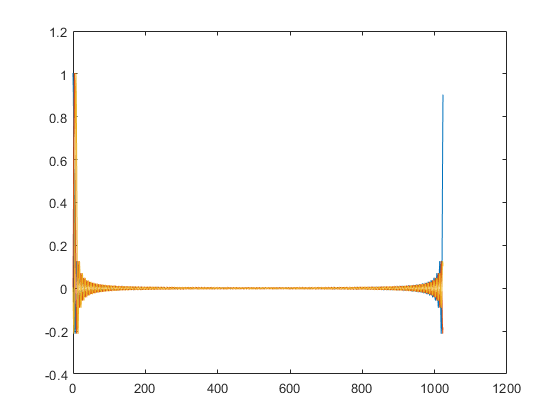


for ix=0:255,
B4(:,ix+1)=circshift(rect4,4*ix);
end
figure(10);plot(0:1023,B4(:,[1 2 3])');

## QUESTION: What do the reconstructing functions look like in this case? Are they as you expected? 

translated sincs but more dense as expected

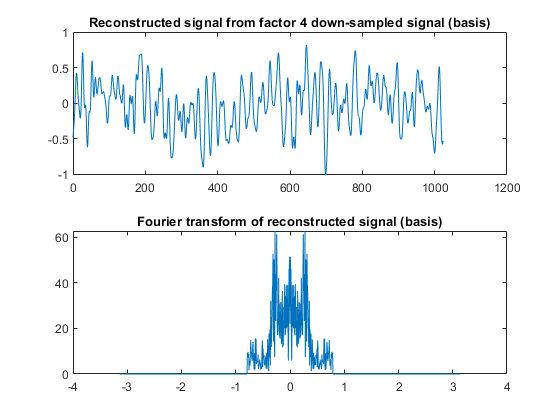

sblrec4b=B4*downsampl4n;
figure(11);subplot(2,1,1);plot(0:1023,sblrec4b);
title('Reconstructed signal from factor 4 down-sampled signal (basis)');
subplot(2,1,2);plot(u,abs(fftshift(fft(sblrec4b))));
title('Fourier transform of reconstructed signal (basis)');

err=sbl-sblrec4b;
fprintf('Reconstruction from factor 4 down-sampled signal (basis)\n');

Reconstruction from factor 4 down-sampled signal (basis)


fprintf('Reconstruction error: mean %f std %f\n',mean(err),std(err));

Reconstruction error: mean -0.001404 std 0.111932


## QUESTION: What amount of noise do you get (mean and standard deviation)? Is it consistent with your answer to preparatory exercise 7? 

mean 0 and std 0.1

## Use the Matlab code that you wrote in preparatory exercise 9 to check that B4 is a basis. QUESTION: Does it give you the expected answer? 

[U S V] = svd(B4);
B4basis = (sum(diag(S)==0) == 0) % 1 if basis, 0 if not

B4basis = logical
   1


## 3.4 Over-sampling, reconstruction with a frame

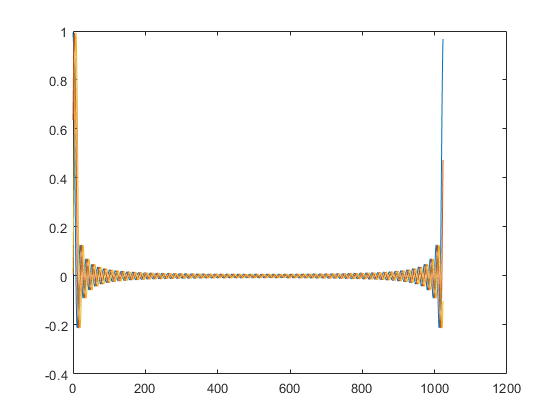

for ix=0:255,
F8(:,ix+1)=circshift(rect8,4*ix);
end
figure(13);plot(0:1023,F8(:,[1 2 3])');

#### QUESTION: What do these functions look like? How do they differ from the reconstructing functions in the previous exercise? Compare!

Similar density but lower frequency

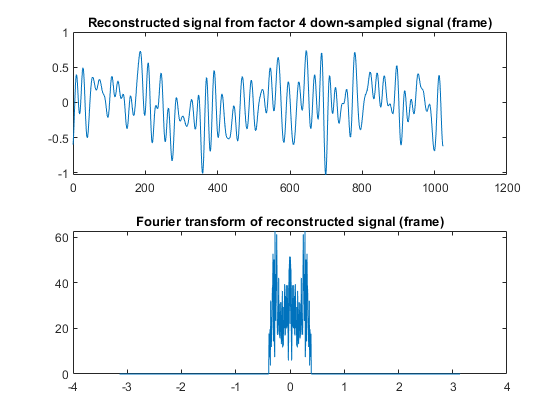

sblrec4f=0.5*F8*downsampl4n;
figure(15);
subplot(2,1,1);plot(0:1023,sblrec4f);
title('Reconstructed signal from factor 4 down-sampled signal (frame)');
subplot(2,1,2);plot(u,abs(fftshift(fft(sblrec4f))));
title('Fourier transform of reconstructed signal (frame)');

err=sbl-sblrec4f;
fprintf('Reconstruction from factor 4 down-sampled signal (frame)\n');

Reconstruction from factor 4 down-sampled signal (frame)


fprintf('Reconstruction error: mean %f std %f\n',mean(err),std(err));

Reconstruction error: mean -0.001404 std 0.072859


#### QUESTION: Did you get a noise level in accordance with preparatory exercise 10?

Mean 0 and std 0.07 or 1/sqrt(2)*0.1 so yes.

#### Do the same check as you did in the last exercise, now to confirm that F8 holds a proper frame rather than a basis in its columns. QUESTION: Is it a proper frame?

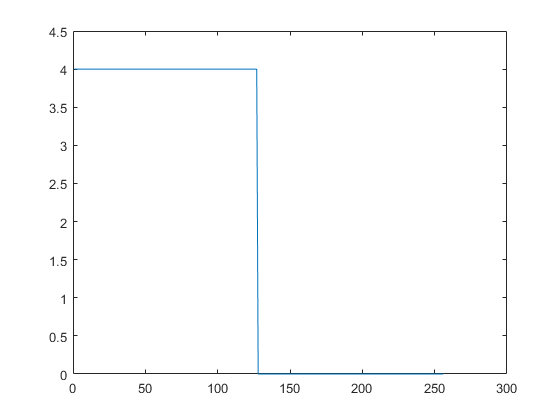

[U S V] = svd(F8);
figure
plot(diag(S))

F8frame = (sum(abs(diag(S))<1e-12) == 0) % 1 if frame, 0 if not

F8frame = logical
   0


clear
close all
clf

## 4.1 The two-channel filter bank 

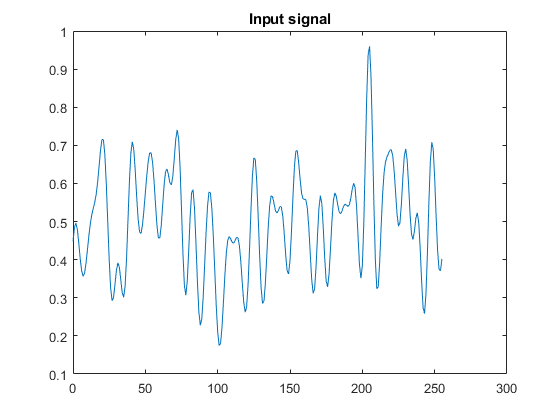

l=256;
u=((-l/2):(l/2-1))*2*pi/l;
s0=rand(1,l);
S0=fftshift(fft(ifftshift(s0)));
S=S0.*(abs(u)<pi/4);
s=real(ifftshift(ifft(fftshift(S))));
figure(21);plot(0:255,s);
title('Input signal');


[h0 g0 h1 g1]=wfilters('db3')

h0 =     0.0352   -0.0854   -0.1350    0.4599    0.8069    0.3327


g0 =    -0.3327    0.8069   -0.4599   -0.1350    0.0854    0.0352


h1 =     0.3327    0.8069    0.4599   -0.1350   -0.0854    0.0352


g1 =     0.0352    0.0854   -0.1350   -0.4599    0.8069   -0.3327


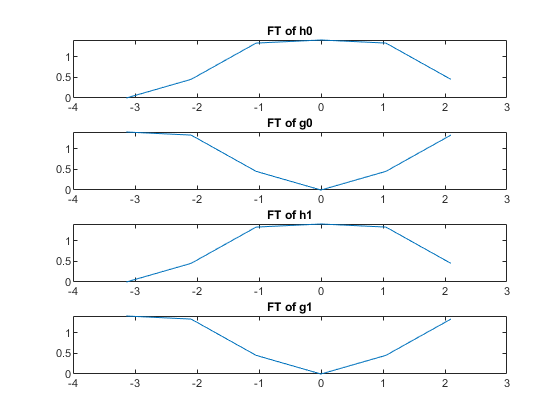


flength=length(h0);
u1=((-flength/2):(flength/2-1))*2*pi/flength;
figure(22);
subplot(4,1,1);plot(u1,abs(fftshift(fft(h0))));title('FT of h0');
subplot(4,1,2);plot(u1,abs(fftshift(fft(g0))));title('FT of g0');
subplot(4,1,3);plot(u1,abs(fftshift(fft(h1))));title('FT of h1');
subplot(4,1,4);plot(u1,abs(fftshift(fft(g1))));title('FT of g1');

## QUESTION: How would you characterise the filters in terms of their frequency response functions? 

h0, h1 bandpass filters, g0 g1 bandstop filters

## QUESTION: Are the filter coefficients related to each other in the way you expected?

Since these are real filters these are expected.

dwtmode('per'); %Set periodic mode of filtering operations

                                         
*****************************************
**  DWT Extension Mode: Periodization  **
*****************************************
                                         


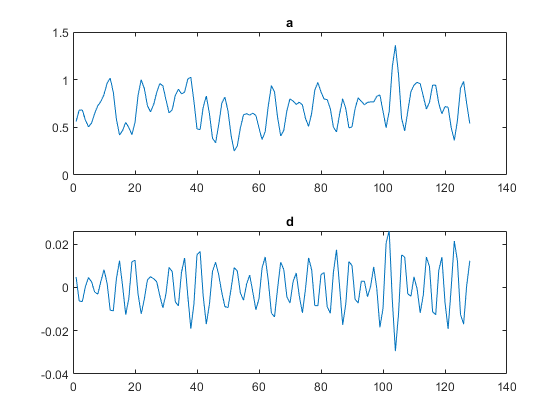

[a d]=dwt(s,h0,g0); 
figure(3);
subplot(2,1,1);plot(a);title('a');
subplot(2,1,2);plot(d);title('d');

## QUESTION: How would you characterise the two signals a and d?

a has lower frequencies with high amplitude while d has higher frequencies of sinusoids with low amplitudes.

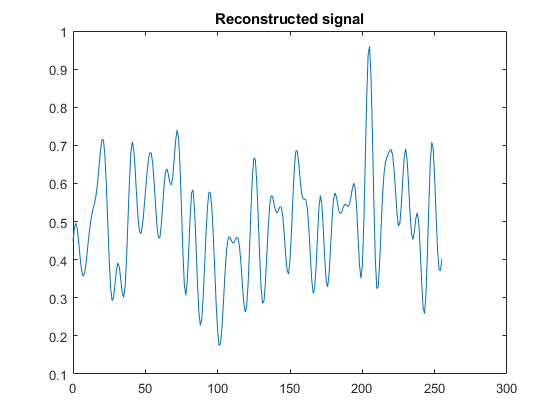

srec1=idwt(a,d,h1,g1);
figure(4);plot(0:255,srec1);
title('Reconstructed signal');


sum(s-srec1) %approx 0 if good reconstruction

ans = -4.3965e-14

#### **QUESTION: The reconstructed signal should be equal to the input signal. Verify this. Are they equal?**

Yes

## 4.2 Multi-level filter bank

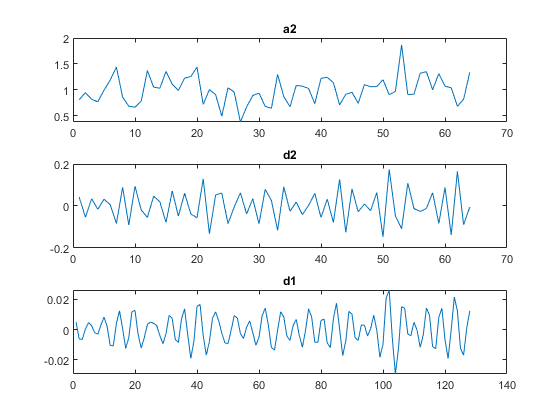

[a1 d1]=dwt(s,h0,g0);
[a2 d2]=dwt(a1,h0,g0);
figure(5);
subplot(3,1,1);plot(a2);title('a2');
subplot(3,1,2);plot(d2);title('d2');
subplot(3,1,3);plot(d1);title('d1');

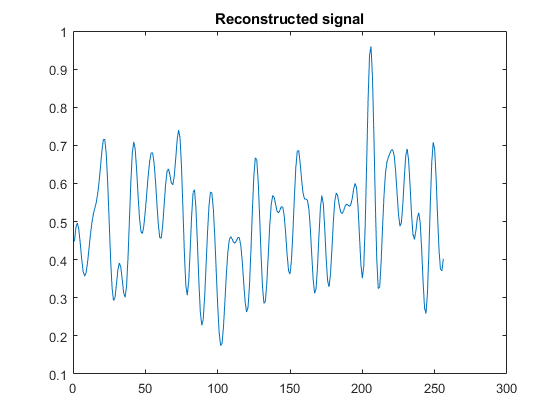


a1rec=idwt(a2,d2,h1,g1);
srec2=idwt(a1rec,d1,h1,g1);
figure(6);plot(srec2);title('Reconstructed signal');

sum(s-srec2)

ans = -8.6181e-14

#### QUESTION: Verify that the reconstructed signal equals the input signal. Are they equal?

Yes

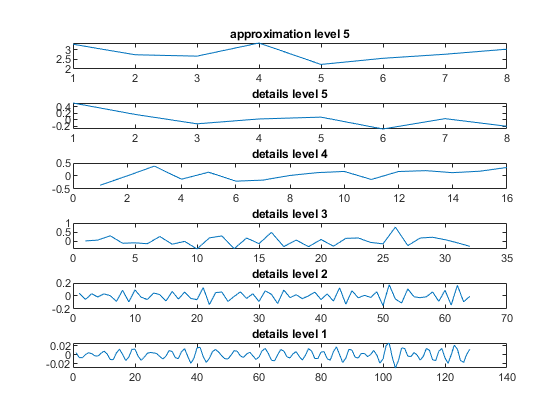

% Code snippet (A)
N=5;ad=s;p=length(s);figure(7);
for cnt=1:N,
[a d]=dwt(ad(1:p),h0,g0);
ad(1:p)=[a d];
subplot(N+1,1,N+2-cnt);
plot(d);title(sprintf('details level %d',cnt));
p=p/2;
end
subplot(N+1,1,1);plot(a);
title(sprintf('approximation level %d',cnt));

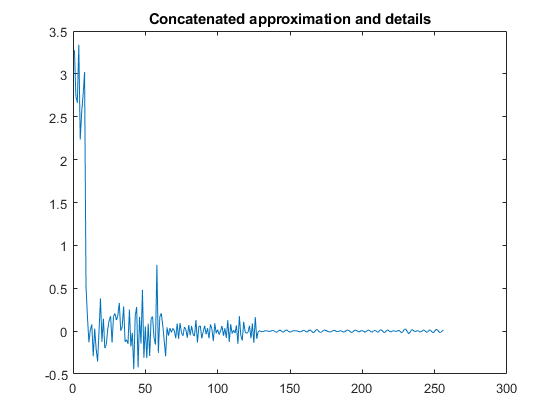

figure(8);plot(ad);
title('Concatenated approximation and details');


% Code snippet (B)
for cnt=1:N,
ad(1:(2*p))=idwt(ad(1:p),ad((p+1):(2*p)),h1,g1);
p=2*p;
end
figure(9);plot(ad);title('Reconstructed signal');


sum(ad-s)

ans = 2.1036e-13

#### QUESTION: Is the reconstructed signal in figure 9 equal to the input signal, figure 1?

Yes

## 4.3 Simple signal compression

#### QUESTION: If you use some reasonable value for N and consider the approximation and detail signals, how would you implement such a quantisation? Which components seem to need more bits than others?

Since less decomposed signals will be longer they should have more bits than the more decomposed signals.

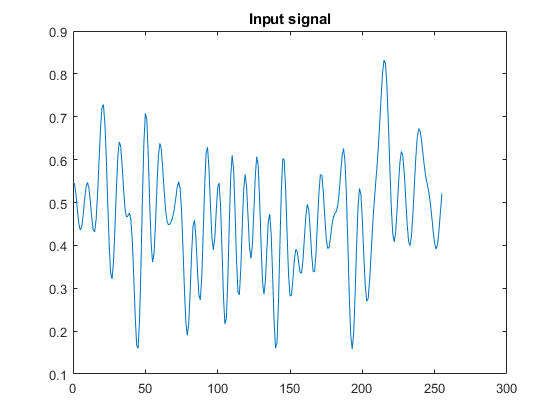

% generate signal
l=256;
u=((-l/2):(l/2-1))*2*pi/l;
s0=rand(1,l);
S0=fftshift(fft(ifftshift(s0)));
S=S0.*(abs(u)<pi/4);
s=real(ifftshift(ifft(fftshift(S))));
figure(21);plot(0:255,s);
title('Input signal');

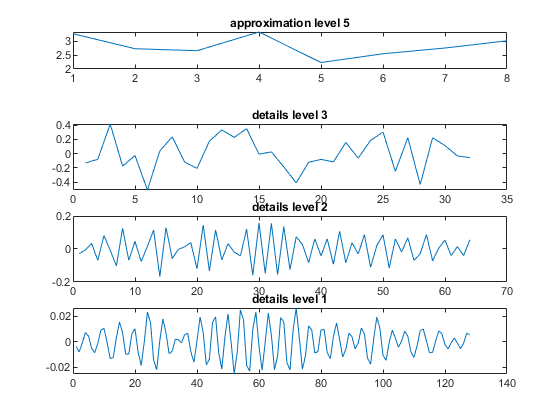

% Code snippet (A)
N=3;ad=s;p=length(s);figure(7);
for cnt=1:N,
[a d]=dwt(ad(1:p),h0,g0);
ad(1:p)=[a d];

subplot(N+1,1,N+2-cnt);
plot(d);title(sprintf('details level %d',cnt));
p=p/2;
end

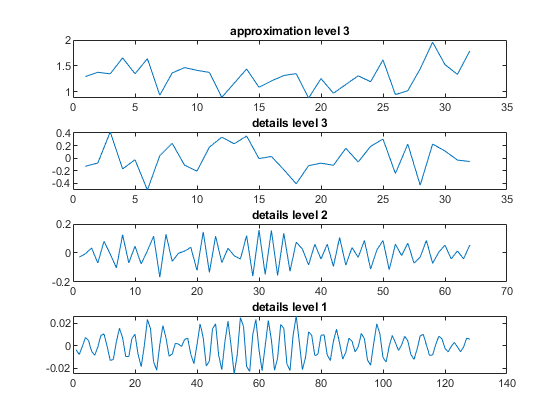

subplot(N+1,1,1);plot(a);
title(sprintf('approximation level %d',cnt));

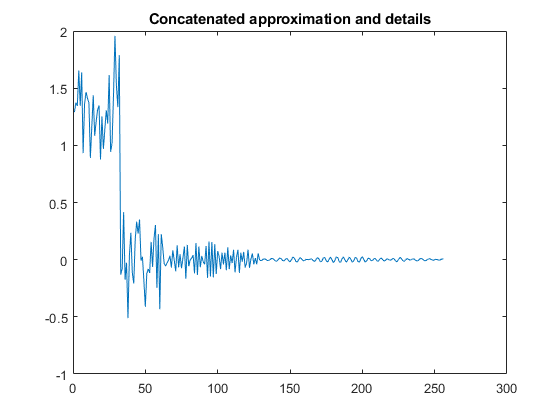

figure(10);plot(ad);
title('Concatenated approximation and details');

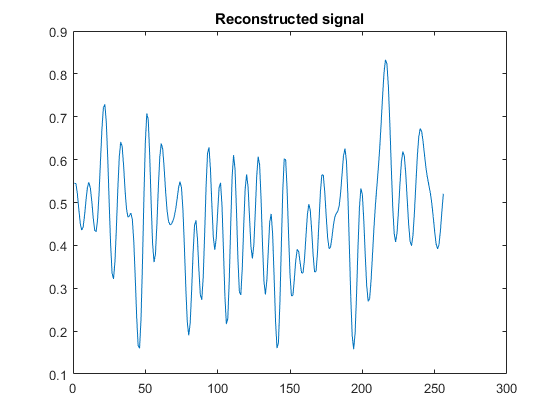


% quantisize ad
q = [16 3;
    16 2;
    16 1;
    16 0.1];
[ad bps] = quantisead(ad,q);

% Code snippet (B)
for cnt=1:N,
ad(1:(2*p))=idwt(ad(1:p),ad((p+1):(2*p)),h1,g1);
p=2*p;
end
figure(9);plot(ad);title('Reconstructed signal');

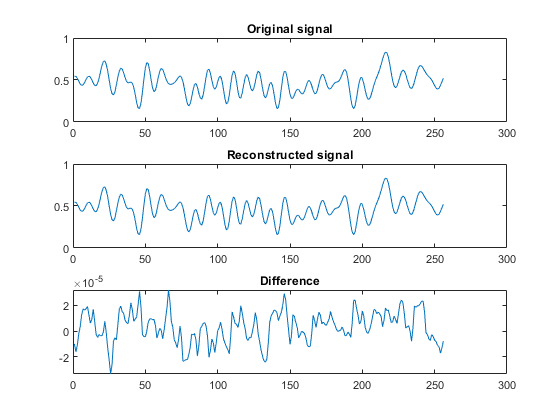


figure(100);
subplot(3,1,1);plot(s);title('Original signal');
subplot(3,1,2);plot(ad);title('Reconstructed signal');
subplot(3,1,3);plot(s-ad);title('Difference');

SNR=log10(max(s)/std(ad-s))*20

SNR = 96.8718

bps

bps = 16

#### QUESTION: What SNR do you get? What is the average number of bits per sample?

SNR 96.4656, bps 16

clear
close all
clf

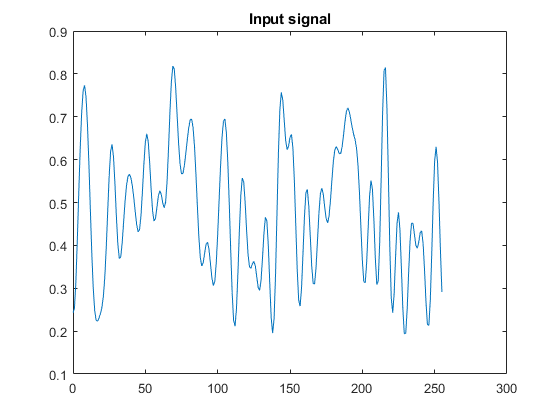

% generate signal
l=256;
u=((-l/2):(l/2-1))*2*pi/l;
s0=rand(1,l);
S0=fftshift(fft(ifftshift(s0)));
S=S0.*(abs(u)<pi/4);
s=real(ifftshift(ifft(fftshift(S))));
figure(21);plot(0:255,s);
title('Input signal');

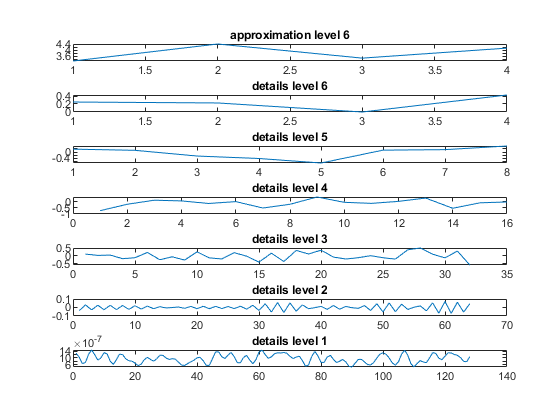

% Code snippet (A)
N = 6;
qbits = [8 7 6 5 4 3 1];
q = zeros((N+1),2);
q(:,1) = qbits;
[h0 g0 h1 g1]=wfilters('dmey');



ad=s;p=length(s);figure(7);
for cnt=1:N,
[a d]=dwt(ad(1:p),h0,g0);
ad(1:p)=[a d];

subplot(N+1,1,N+2-cnt);
plot(d);title(sprintf('details level %d',cnt));
p=p/2;
end
subplot(N+1,1,1);plot(a);
title(sprintf('approximation level %d',cnt));

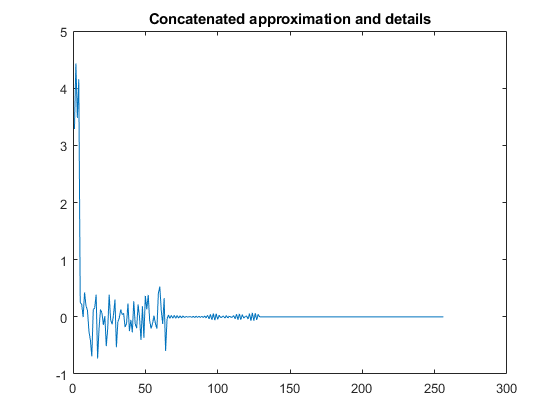

figure(10);plot(ad);
title('Concatenated approximation and details');

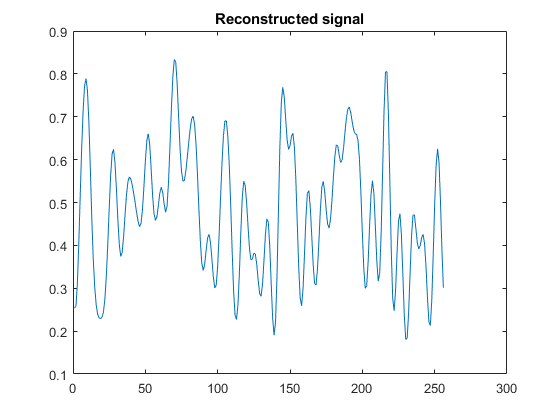


% quantisize ad
p_tmp = p;
ad_tmp = ad;

    % optimize range
for i = 1:N+1
   q(i,2) = max(abs(ad_tmp(1:p_tmp)));
   ad_tmp = ad_tmp(p_tmp+1:end);
   if i > 1
        p_tmp = 2*p_tmp;
   end
end

[ad bps] = quantisead(ad,q);

% Code snippet (B)
for cnt=1:N,
ad(1:(2*p))=idwt(ad(1:p),ad((p+1):(2*p)),h1,g1);
p=2*p;
end
figure(9);plot(ad);title('Reconstructed signal');

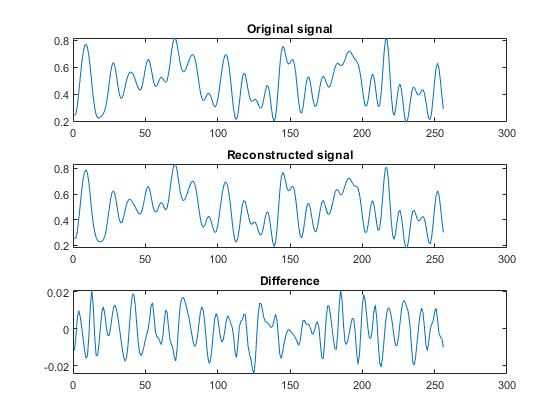


figure(100);
subplot(3,1,1);plot(s);title('Original signal');
subplot(3,1,2);plot(ad);title('Reconstructed signal');
subplot(3,1,3);plot(s-ad);title('Difference');

SNR=log10(max(s)/std(ad-s))*20

SNR = 38.5953

bps

bps = 2.4844

J0XE-7EM1

SGEZ-QYB9

JUR0-XKV3